nums = [20:40];
acctrains = [];   %zeros(1,length(nums))
acctests = [];

tic
for i = nums
    
    data = X;
    label = y;
    [vsel_spa] = feature_spa(data, 20, i)
    
    group = string(y);
    group(group == "1") = "zd958";
    group(group == "2") = "jd20";
    group(group == "3") = "nh816";
    group(group == "4") = 'jh5';

    data = X;
    label = group;

    train_data  = data(training(cvp), vsel_spa);
    train_label = label(training(cvp));
    test_data   = data(test(cvp), vsel_spa);
    test_label  = label(test(cvp));

    rng(1); % For reproducibility
    randIndex1 = randperm(size(train_data,1));
    rng(1); % For reproducibility
    randIndex2 = randperm(size(test_data,1));

    train_data  = train_data(randIndex1, :);
    train_label = train_label(randIndex1);
    test_data   = test_data(randIndex2, :);
    test_label  = test_label(randIndex2);

    rng(1); % For reproducibility
    Mdl = TreeBagger(100, train_data, train_label, 'OOBPrediction', 'On', 'Method', 'classification')

    % view(Mdl.Trees{1},'Mode','graph')
    % figure;
    % oobErrorBaggedEnsemble = oobError(Mdl);
    % plot(oobErrorBaggedEnsemble)
    % xlabel 'Number of grown trees';
    % ylabel 'Out-of-bag classification error';

    simy1 = predict(Mdl, train_data);
    simy2 = predict(Mdl, test_data);

    s1 = length(simy1) ;
    hitNum1 = 0 ;
    for k = 1:s1
        if( simy1(k) == train_label(k))
            hitNum1 = hitNum1 + 1 ;
        end
    end
    sprintf('识别率是 %3.3f%%', 100 * hitNum1 / s1 )

    s2 = length(simy2) ;
    hitNum2 = 0 ;
    for j = 1:s2
        if( simy2(j) == test_label(j))
            hitNum2 = hitNum2 + 1 ;
        end
    end
    sprintf('识别率是 %3.3f%%', 100 * hitNum2 / s2 )
    
    acctrains = [acctrains, 100 * hitNum1 / s1];
    acctests = [acctests, 100 * hitNum2 / s2];    

end

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x20]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   20
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 94.444%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x21]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   21
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 94.444%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x22]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   22
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 93.889%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x23]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   23
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 93.333%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x24]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   24
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 93.889%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x25]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   25
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 96.111%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x26]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   26
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 95.000%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x27]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   27
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 95.556%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x28]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   28
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 96.667%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5   239


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x29]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   29
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 96.111%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5   239   283


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x30]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   30
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 96.667%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5   239   283   341


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x31]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   31
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 97.222%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5   239   283   341   302


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x32]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   32
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 96.667%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5   239   283   341   302   381


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x33]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   33
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 97.222%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5   239   283   341   302   381     4


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x34]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   34
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 96.667%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5   239   283   341   302   381     4   378


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x35]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   35
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 96.667%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5   239   283   341   302   381     4   378   237


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x36]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   36
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 96.111%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5   239   283   341   302   381     4   378   237   284


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x37]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   37
         NumPredictorsToSample:                    7
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 96.111%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5   239   283   341   302   381     4   378   237   284   311


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x38]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   38
         NumPredictorsToSample:                    7
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 96.111%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5   239   283   341   302   381     4   378   237   284   311   265


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x39]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   39
         NumPredictorsToSample:                    7
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 96.667%'

vsel_spa =     20   324   325   323   322   326   321   320   327   334   333   332   331   335   330   319   328   329   336   318   340   339   337   338   380   379   238     5   239   283   341   302   381     4   378   237   284   311   265     3


Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x40]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   40
         NumPredictorsToSample:                    7
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


ans = '识别率是 100.000%'

ans = '识别率是 96.111%'

acctrains

acctrains =    100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100


acctests

acctests =        94.444       94.444       93.889       93.333       93.889       96.111           95       95.556       96.667       96.111       96.667       97.222       96.667       97.222       96.667       96.667       96.111       96.111       96.111       96.667       96.111


nums

nums =     20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40


[vsel_spa] = feature_spa(data(training(cvp), :), 20, 31)

vsel_spa =     20   324   325   323   326   322   327   321   334   335   333   320   328   336   332   330   331   329   189   319   190   181   188   182   180   337   191   187   183   339   173



group = string(y_noout);
group(group == "1") = "zd958";
group(group == "2") = "jd20";
group(group == "3") = "nh816";
group(group == "4") = 'jh5';

data = X_noout;
label = group;

train_data  = data(training(cvp), vsel_spa);
train_label = label(training(cvp));
test_data   = data(test(cvp), vsel_spa);
test_label  = label(test(cvp));

rng(1); % For reproducibility
randIndex1 = randperm(size(train_data,1));
rng(1); % For reproducibility
randIndex2 = randperm(size(test_data,1));

train_data  = train_data(randIndex1, :);
train_label = train_label(randIndex1);
test_data   = test_data(randIndex2, :);
test_label  = test_label(randIndex2);

valid_data = X_valid_noout(:, vsel_spa);
group1 = string(y_valid_noout);
group1(group1 == "1") = "zd958";
group1(group1 == "2") = "jd20";
group1(group1 == "3") = "nh816";
group1(group1 == "4") = 'jh5';
valid_label = group1;

rng(1); % For reproducibility
Mdl = TreeBagger(100, train_data, train_label, 'OOBPrediction', 'On', 'Method', 'classification')

Mdl =   TreeBagger
集成了 100 个装袋决策树:
                    Training X:             [420x31]
                    Training Y:              [420x1]
                        Method:       classification
                 NumPredictors:                   31
         NumPredictorsToSample:                    6
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:          'jd20'           'jh5'         'nh816'         'zd958'

  Properties, Methods


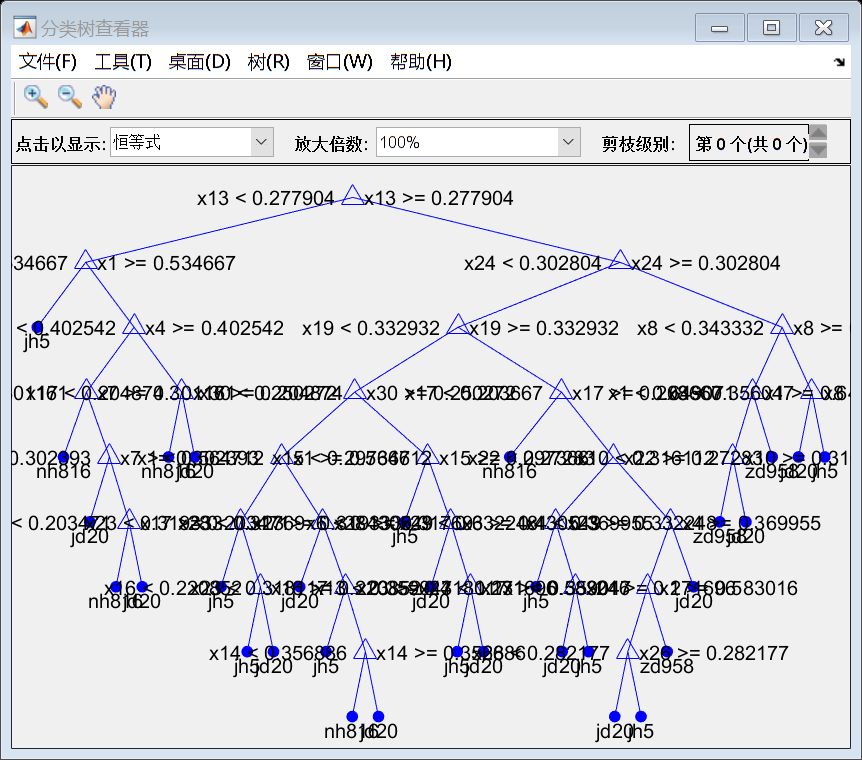


view(Mdl.Trees{1},'Mode','graph')

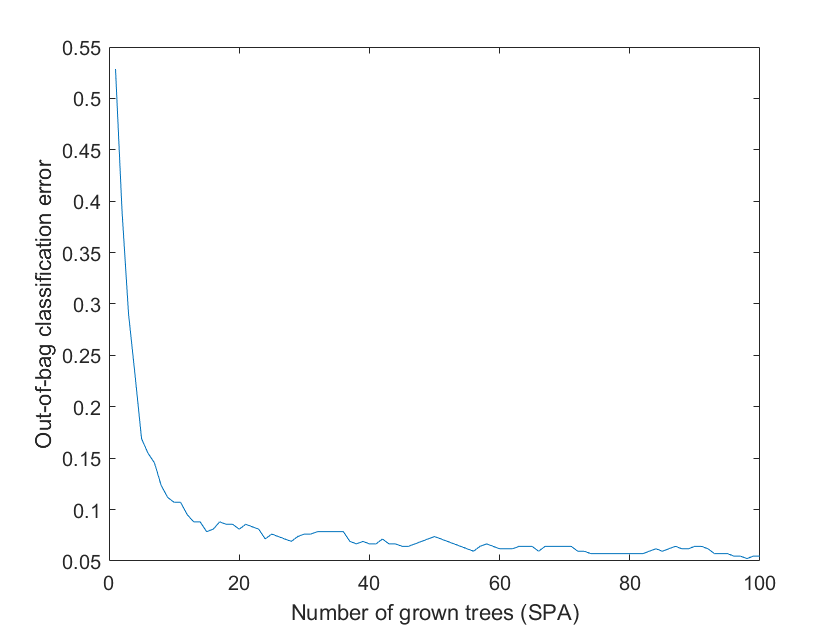

figure;
oobErrorBaggedEnsemble_spa = oobError(Mdl);
plot(oobErrorBaggedEnsemble_spa)
xlabel 'Number of grown trees (SPA)';
ylabel 'Out-of-bag classification error';


simy1 = predict(Mdl, train_data);
simy2 = predict(Mdl, test_data);
simy3 = predict(Mdl, valid_data);

s1 = length(simy1) ;
hitNum1 = 0 ;
for k = 1:s1
    if( simy1(k) == train_label(k))
        hitNum1 = hitNum1 + 1 ;
    end
end
sprintf('识别率是 %3.3f%%', 100 * hitNum1 / s1 )

ans = '识别率是 100.000%'


s2 = length(simy2) ;
hitNum2 = 0 ;
for j = 1:s2
    if( simy2(j) == test_label(j))
        hitNum2 = hitNum2 + 1 ;
    end
end
sprintf('识别率是 %3.3f%%', 100 * hitNum2 / s2 )

ans = '识别率是 95.531%'


s3 = length(simy3) ;
hitNum3 = 0 ;
for j = 1:s3
    if( simy3(j) == valid_label(j))
       hitNum3 = hitNum3 + 1 ;
    end
end
sprintf('识别率是 %3.3f%%', 100 * hitNum3 / s3 )

ans = '识别率是 90.000%'